# Signal Processing Coursework 

**Signal ID: 69**

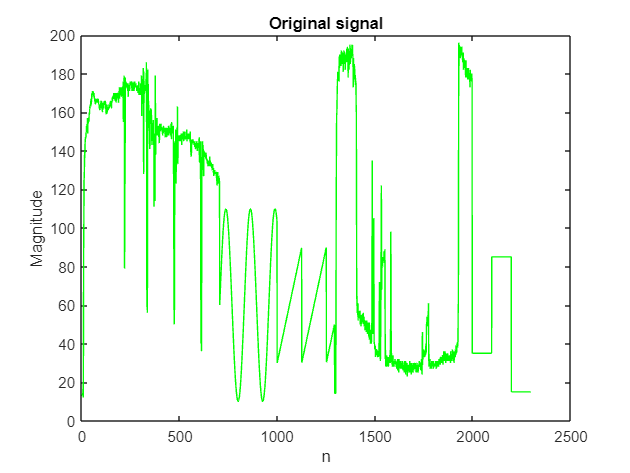

plot(signal,'g');
xlabel("n");
ylabel("Magnitude");
title('Original signal');

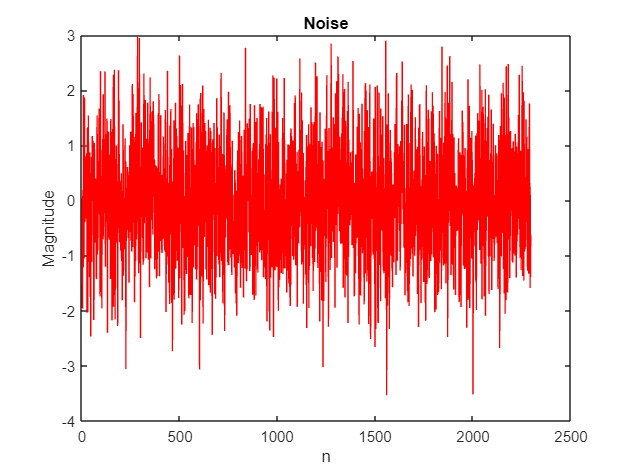

plot(noise,'r');
xlabel("n");
ylabel("Magnitude");
title("Noise");

Determine time domain and frequency domain of the original signal. 

**Adding two signals together **

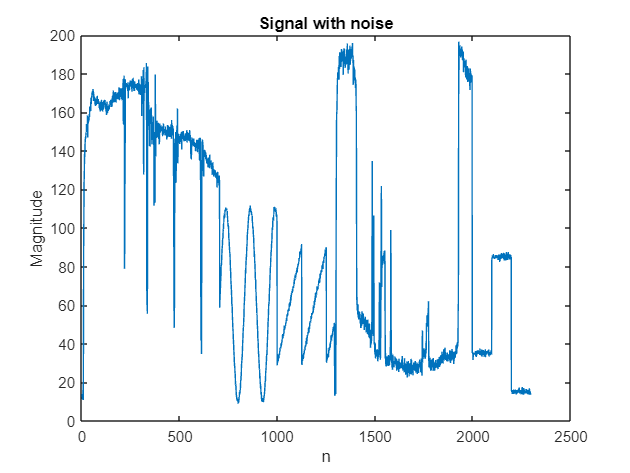

NoisySig= signal+noise;
plot(NoisySig);
ylabel("Magnitude");
xlabel("n");
title('Signal with noise');

### Time domain properties 

Apply difference filter to identify the edges (differences between adjecent values). 

Time domain allows seeing how signal varies accross the time. The in-built diff function calculates differences between adjacent elements of signal. It is clearly visible that there are quite a few edges and many homogenous regions. 

Therefore to identify all edges and divide signal into smaller segments of similar time-domain properties, find function was utilised. 

Important to note, DiffFilter's lenght (number of values) is smaller by one compare to signal's length. It's important to bear that in mind when dividing into segments. 

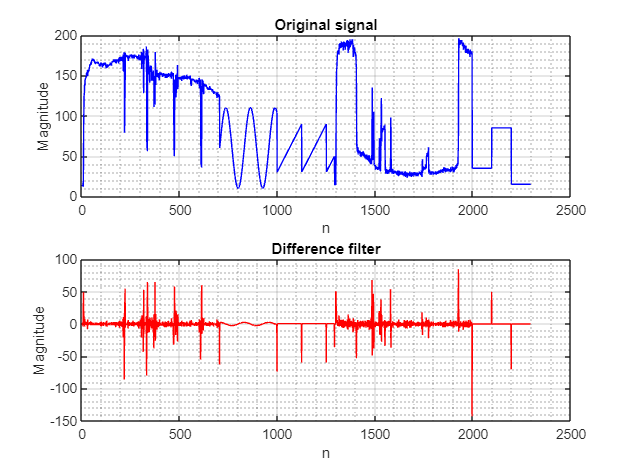

Samples = length(signal); %get number of samples in the signal
DiffFilter = diff(signal); %apply difference filter 
subplot(2,1,1);
plot(signal,"b");
xlabel("n");
ylabel("Magnitude");
grid on;
grid minor;
title("Original signal");
%hold on;
subplot(2,1,2);
plot(DiffFilter, "r");
%hold off;
grid on;
grid minor;
xlabel("n");
ylabel("Magnitude");
title("Difference filter");

%legend("Original signal","DiffFilter signal");

%legend("Position", [0.15008,0.13384,0.25197,0.090599])

#### Edges 

Find function to identify all edges. It looks for all the values within DiffFilter with its absolute values greater than the specified threshold and locates all the spikes. 

**(Double check how to specify the threshold name with lecturer)**

Threshold = 60; %threshold to specify from what values to identify the edges
Spikes = find(abs(DiffFilter)>Threshold);
%plot(Spikes);
%grid on; 
%grid minor;

First rapid spikes observed at 217 

First segment - homogenous region, between 1-217 locations so **first edge 217**

few spikes then up to **704** location - another homogenous region 

then no spikes up to **998**

another region - up to **1292**

then quite a few spikes up to **1581**

then another big spike is **1996**

and then up to the end 

**Remove the DC component to see other values - first and last values of the signal. Just for visualisation **

**can add threshold - higher just to show it's automated **

**Evaluate different lenghts and different number of passees. Just call it few times to a same signal. Show improvement. At some point it gets worse - evaluate it. **

**MSE is not good because one spike and the rest is fine and it does not give you great results. Can add it in conclusions **

### Frequency domain properties 

Extract segments from the original signal



segments = cell(1,7); % Create a cell array with 7 elements (one for each segment)
segments{1} = signal(1:217); 
segments{2} = signal(218:705); 
segments{3} = signal(706:998);
segments{4} = signal(999:1292);
segments{5} = signal(1293:1581);
segments{6} = signal(1582:1996);
segments{7} = signal(1997:end);

%create cell to store noisysegments 
NoisySegments = cell(1,7);
NoisySegments{1} = NoisySig(1:217);
NoisySegments{2} = NoisySig(218:705);
NoisySegments{3} = NoisySig(706:998);
NoisySegments{4} = NoisySig(999:1292);
NoisySegments{5} = NoisySig(1293:1581);
NoisySegments{6} = NoisySig(1582:1996);
NoisySegments{7} = NoisySig(1997:end);


**Update the lengths **

FFT - frequency domain properties 

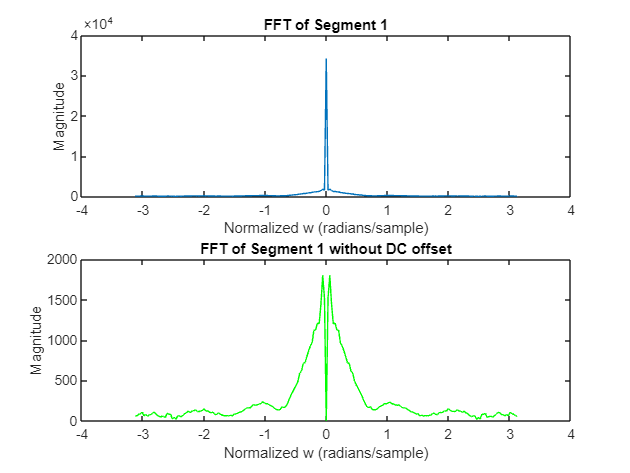

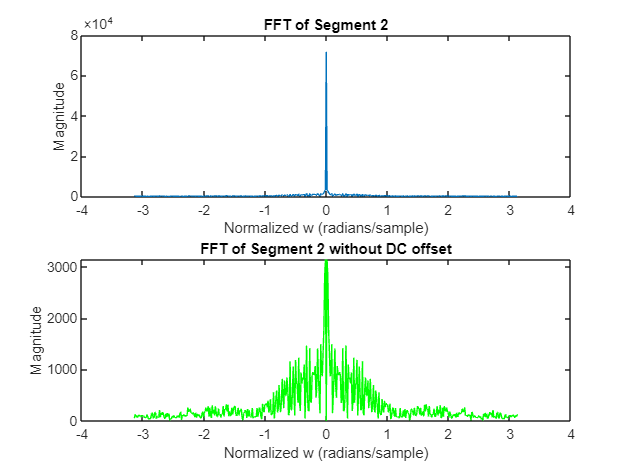

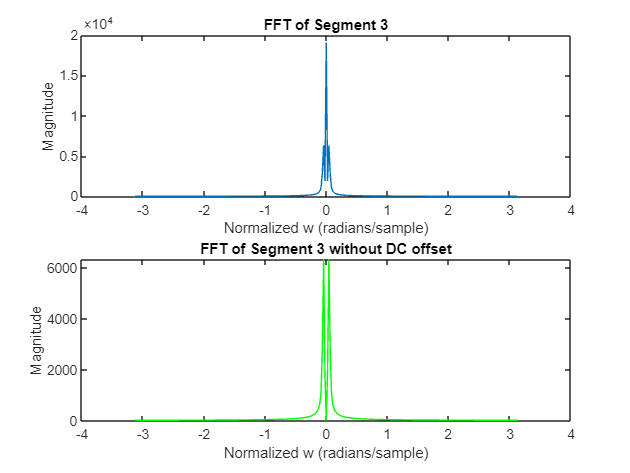

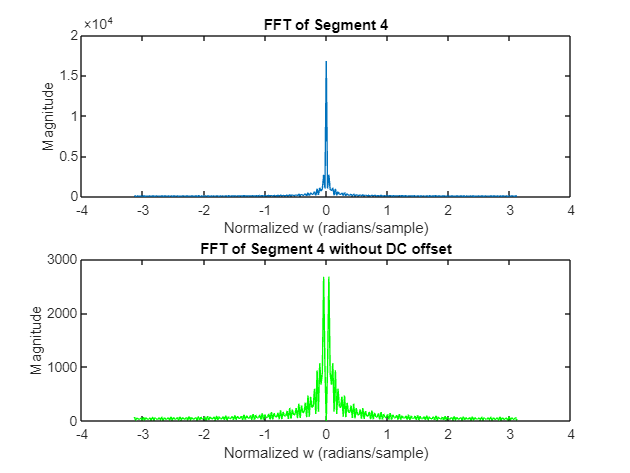

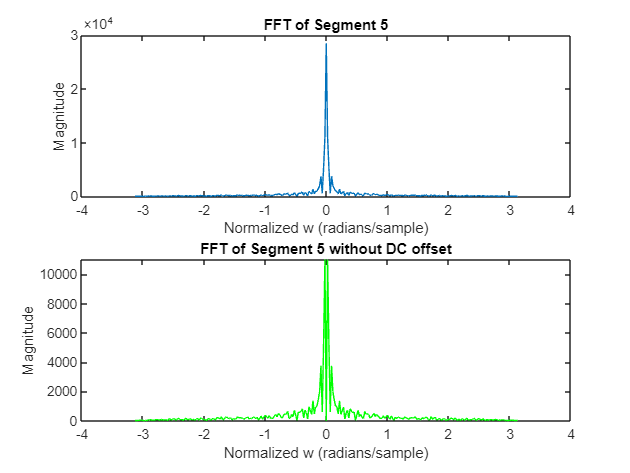

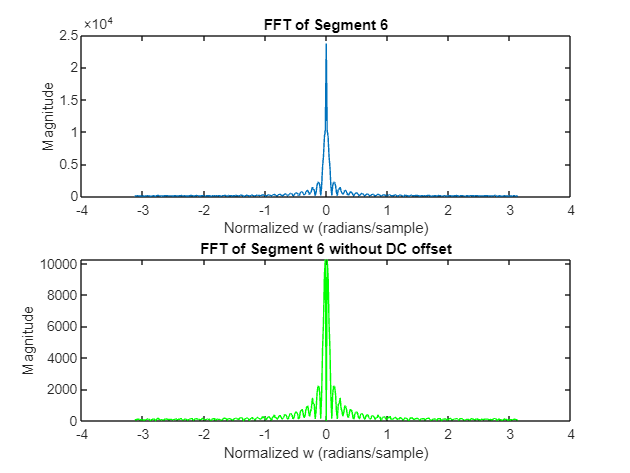

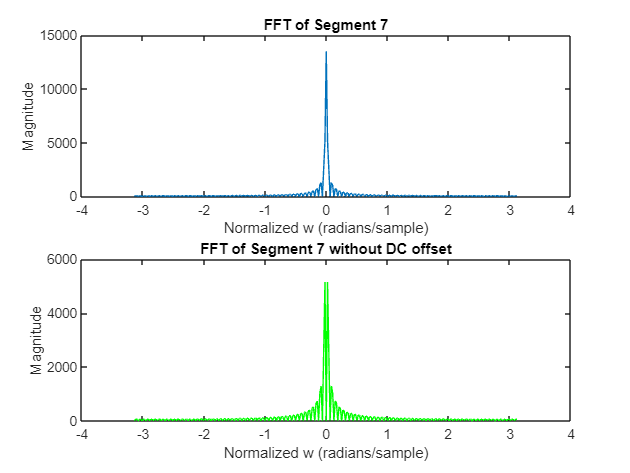

numSegments = 7;

% Create cell arrays to store FFT and f values for each segment
f = cell(1, numSegments);
FT = cell(1, numSegments);
f_noDC = cell(1, numSegments);
FT_noDC = cell(1, numSegments);

% Loop through each segment in the cell array
for segmentIdx = 1:numSegments
  segment = segments{segmentIdx}; % Access the current segment

  % Perform calculations for the current segment
  [f{segmentIdx}, FT{segmentIdx}] = NiceFFT(segment);
  [f_noDC{segmentIdx}, FT_noDC{segmentIdx}] = FFT_noDC(segment);

  figure
  subplot(2,1,1)
  plot(f{segmentIdx},abs(FT{segmentIdx}));
  title(sprintf("FFT of Segment %d", segmentIdx));
  xlabel("Normalized w (radians/sample)");
  ylabel("Magnitude");

  subplot(2,1,2)
  plot(f_noDC{segmentIdx},abs(FT_noDC{segmentIdx}),'g');
  title(sprintf("FFT of Segment %d without DC offset", segmentIdx));
  xlabel("Normalized w (radians/sample)");
  ylabel("Magnitude");
end

The presence of strong frequency components in the signal is indicated by the highest spikes. The prominence of these spikes suggests that certain frequencies in the signal are considerably stronger than others. The dominant frequency component in the signal is close to 0 Hz or DC (direct current) if there is most density around the 0 point of the FFT. A strong low-frequency or DC component in the signal can imply the existence of a significant offset or bias in practical terms. In signal processing, a strong low-frequency component might indicate a trend or baseline in the data.

From FFT can be seen very low frequencies are dominant for all segments so MAF is good as it preserves very low frequencies well and attenuates high frequencies 

DC offset 

DC offset, in the context of signals, refers to a constant voltage or current value that gets added to a signal that otherwise alternates around zero. It's essentially a bias that shifts the entire signal up or down on the vertical axis.

**Causes of DC Offset:**

- Imperfect electronic components:  Electronic components like capacitors can leak a small amount of DC current, introducing an offset.

- Faulty equipment:  Damaged cables or malfunctioning devices can introduce DC offset.

- Signal coupling:  In some cases, unwanted DC voltage from other sources can couple into your signal.

## Feedback 

 Then use the frequency domain properties of the signal segments to determine which length of MAFs should be applied on these segments. You so not have to concatenate the segments back to form the original signal. You should compute the MSE for segments separately and plot segments separately.

**Remove the DC component to see other values - first and last values of the signal. Just for visualisation **

**can add threshold - higher just to show it's automated **

**Evaluate different lenghts and different number of passees. Just call it few times to a same signal. Show improvement. At some point it gets worse - evaluate it. **

**MSE is not good because one spike and the rest is fine and it does not give you great results. Can add it in conclusions **

This is the whole point of this assignment and this is an excellent question.

Firstly make sure you compute the MSE for segments not for the whole signal.  The lower the MSE the similar the recovered signal to the original signal. But lower the MSE does not mean that all noise is removed. After doing this assignment you will realise the method you apply does not only remove noise, it will also modify the original signal. So, to have a lower MSE, the method must remove noise and it must not modify the original signal features. When you look at the frequency domain properties of the signal segments you will see that for some segments, your methods cannot preserve all the signal components. Therefore you will see an increase in MSE  for some segments.

Also make sure the increase in MSE is not due to an error in your implementation.

### MSE 

In signal processing, the mean squared error (MSE) is a metric used to quantify the difference between an estimated signal (your processed or filtered signal) and the original desired signal. It reflects how closely your processing matches the ideal outcome.

- **Lower MSE is generally better:** It signifies a closer match between the original and processed signal.

- **There's usually a trade-off:**  Achieving very low MSE might require complex processing or be limited by inherent noise in the signal.

**Moving average lenght and numbe rof passes**

**Boundary Effects in Moving Average Filters:**

When applying a moving average filter, the filter window needs to consider data points beyond the current point to calculate the average. This creates a challenge at the beginning and end (boundaries) of the signal where there aren't enough data points on one side of the current point to fill the entire window.

**Impact on Accuracy:**

Including the boundary points in the average would introduce inaccurate values:

- The first few data points would be averaged with nonexistent values before the signal starts.

- The last few data points would be averaged with nonexistent values after the signal ends.

#### 1st segment 

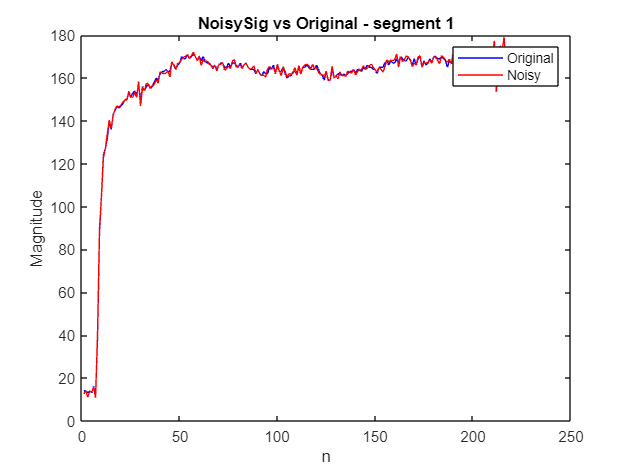

figure
plot(segments{1},'b');
hold on; 
plot(NoisySegments{1},'r');
xlabel("n");
ylabel("Magnitude");
title ('NoisySig vs Original - segment 1');
legend('Original','Noisy');

#### MSE and MAEs noisy signals

%MSE 
for index = 1:length(NoisySegments)
MSENoisy{index} = mean((NoisySegments{index}-segments{index}).*(NoisySegments{index}-segments{index}));
MAENoisy{index} = sum(abs(NoisySegments{index}-segments{index}))/length(NoisySegments{index});
end

MSENoisy = cell2mat(MSENoisy);


#### MAF and MSEs and MAEs calculations 

 

 [MAFFilteredSegment1,MSEFiltered1,MAEFiltered1] = MAF_filter(NoisySegments{1},segments{1},20,5);
 [MAFFilteredSegment2,MSEFiltered2,MAEFiltered2] = MAF_filter(NoisySegments{2},segments{2},20,5);
 [MAFFilteredSegment3,MSEFiltered3,MAEFiltered3] = MAF_filter(NoisySegments{3},segments{3},20,5);
 [MAFFilteredSegment4,MSEFiltered4,MAEFiltered4] = MAF_filter(NoisySegments{4},segments{4},20,5);
 [MAFFilteredSegment5,MSEFiltered5,MAEFiltered5] = MAF_filter(NoisySegments{5},segments{5},20,5);
 [MAFFilteredSegment6,MSEFiltered6,MAEFiltered6] = MAF_filter(NoisySegments{6},segments{6},20,5);
 [MAFFilteredSegment7,MSEFiltered7,MAEFiltered7] = MAF_filter(NoisySegments{7},segments{7},20,5);



#### MAEs

### MAF Performance analysis 

#### Segment1

 %Clean empty cells
 % CleanedMSE1 = MSEFiltered1(cellfun(@isempty,MSEFiltered1) == false);
   EmptyCols = any(cellfun(@isempty, MSEFiltered1),1);
   NotemptyCols = find(~EmptyCols);
   CLeanedMSE1 = MSEFiltered1(:,NotemptyCols);
   NamesCols = {'M = 1','M = 3','M = 5','M = 7','M = 9', 'M = 11', 'M = 13', 'M = 15', 'M = 17', 'M = 19'};
   DimNames = {'Passes - N','Lenghts - M'};
   RowNames = {'N = 1', 'N = 2','N = 3', 'N = 4', 'N = 5'};
  TableTest = cell2table(CLeanedMSE1,"VariableNames",NamesCols,"RowNames",RowNames)

TableTest = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.98199    4.7485    7.9723    12.654    19.089    24.304    25.698    21.114    21.911    25.615
    N = 2    0.98199    5.2315    10.707    18.423    26.328    30.436    33.757    38.337     49.12    54.098
    N = 3    0.98199    6.9886    14.551    24.498    32.373    37.098    45.016    58.963    77.342    81.846
    N = 4    

  writetable(TableTest,'MyTableTest.xls');
  % emptyCols = all(ismissing(TableTest),1);
  % TableTest = TableTest(:,~emptyCols)

**For testing **

 %  %MSE 
% %create cells for MSEs 
% MSENoisy = cell(1,7);
% MSEFiltered = cell(4,15);
% 
% MSENoisy{1} = mean((NoisySegments{3}-segments{3}).*(NoisySegments{3}-segments{3})) 
% 
% %Create a cell to store filtered segments 
% MAFFilteredSegments = cell(4,15);
% 
% 
%  for M = 1:15 %loop for filter lenght
%      %Assign Noise to first cell so MAF can be calculated 
%      % MAFFilteredSegments{1,M} = NoisySegments{1};
%     %n = 2:length(NoisySegments{1});
%     for N=1:4 %loop for number of passes 
%         MAFFilteredSegments{N,M} = NoisySegments{3};
%         for i = 3:291 %loop to iterate through each value in the signal 
%             if N==1 
%              MAFFilteredSegments{N,M}(i) = (NoisySegments{3}(i-2) +NoisySegments{3}(i-1)+ NoisySegments{3}(i) + NoisySegments{3}(i+1)+NoisySegments{3}(i+2))/M;
%             else 
%              MAFFilteredSegments{N,M}(i) = (MAFFilteredSegments{N-1,M}(i-2)+MAFFilteredSegments{N-1,M}(i-1) +MAFFilteredSegments{N-1,M}(i) + MAFFilteredSegments{N-1,M}(i+1)+MAFFilteredSegments{N-1,M}(i+2))/M;
%             end
%         end
%         MSEFiltered{N,M} = mean((MAFFilteredSegments{N,M}-segments{3}).*(MAFFilteredSegments{N,M}-segments{3}));
%     end
%         % MSEFiltered{1,M} = mean((MAFFilteredSegments{1,M}-segments{1}).*(MAFFilteredSegments{1,M}-segments{1}))
% 
%  end

**Create a bar to visualise MSE data**

 figure;

% Number of columns (filter lengths) in MSEFiltered
num_columns = size(MSEFiltered, 2);

Unrecognized function or variable 'MSEFiltered'.


% % Loop through each column (filter length) and create a batch chart
% for col = 1:num_columns
%     % Extract the current column of MSE data and convert to an array 
%     mse_data = reshape(cell2mat(MSEFiltered(:, col)),[1,4]);
%     barData = [barData;mse_data];
%     % % Create a subplot for the current column
%     % subplot(ceil(num_columns/3), 3, col);
% 
%     % % Plot the MSE data as a bar chart
%     % bar(mse_data);
%     % 
%     % % Add labels and title to the subplot
%     % xlabel('Number of Passes (N)');
%     % ylabel('Mean Squared Error (MSE)');
%     % title(['Batch Chart (Filter Length ', num2str(col), ')']);
% end

 % figure 
 % plot(MAFFilteredSegments{1,9},'r');
 % plot(segments{1},'b');

 %MSEFiltered1 = cell2mat(MSEFiltered{1,:});
% figure
% plot(MSEFiltered{1,:});
% x2=y;
% for i=2:255
% x2(i)=(y(i-1)+y(i)+y(i+1))/3;
% end
% MSE2=mean((x2-x).*(x2-x));
% figure;plot(n,y,'b', n, x2, 'g')
% xlabel('n');
% ylabel('Magnitude');
% title ('Q3')
% legend('y','x2')

